# Record Analysis

Checking the Avaneesh dataset and comparing to the Lopez (Abnormal) Set and Original Paper

## Load Datasets

load("PreRecordDatabase.mat");
Avaneesh = CohortFiles(A);
AllFiles = CohortFiles("PreData202012221319.xlsx");
y = load("PrePaper_Tables.mat");
names = fieldnames(y);
categ = [repmat(categorical("Normal"),[height(y.(names{1})),1]);...
    repmat(categorical("Stroke"),[height(y.(names{2})),1]);...
    repmat(categorical("TBI"),[height(y.(names{3})),1])];
Original = [y.(names{1});y.(names{2});y.(names{3})];
Original.Category = categ;
try
    Lopez = load("PreLopezData.mat");
    Lopez = Lopez.T;
catch
    Lopez = GetLopezData("D:\Lopez");
end
disp("Total Dataset")

Total Dataset


NumSubjects(AllFiles);

Number of Total subjects: 15001
Number of Normal subjects: 0
Number of TBI subjects: 0
Number of Stroke subjects: 0


disp("Avaneesh Dataset")

Avaneesh Dataset


NumSubjects(Avaneesh);

Number of Total subjects: 3938
Number of Normal subjects: 1054
Number of TBI subjects: 326
Number of Stroke subjects: 488


disp("Original Dataset")

Original Dataset


disp("Number of Total subjects: " + numel(unique(Original.Subject)))

Number of Total subjects: 487


disp("Number of Normal subjects: " + numel(unique(Original.Subject(Original.Category=="Normal"))))

Number of Normal subjects: 114


disp("Number of TBI subjects: " + numel(unique(Original.Subject(Original.Category=="TBI"))))

Number of TBI subjects: 142


disp("Number of Stroke subjects: " + numel(unique(Original.Subject(Original.Category=="Stroke"))))

Number of Stroke subjects: 232


disp("Lopez Dataset")

Lopez Dataset


disp("Number of Total subjects: " + numel(unique(Lopez.Subject)))

Number of Total subjects: 2329


disp("Number of Normal subjects: " + numel(unique(Lopez.Subject(Lopez.Category=="Normal"))))

Number of Normal subjects: 1385


disp("Number of Abnormal subjects: " + numel(unique(Lopez.Subject(Lopez.Category=="Abnormal"))))

Number of Abnormal subjects: 998


## Compare

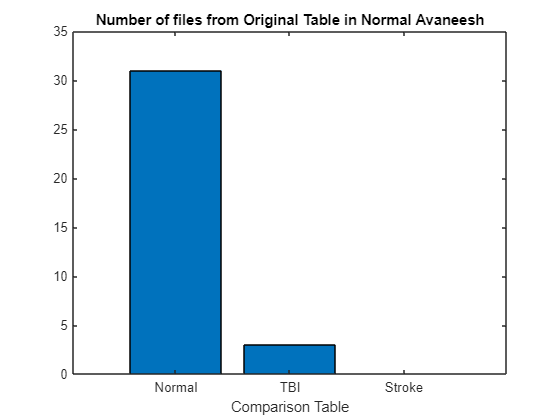

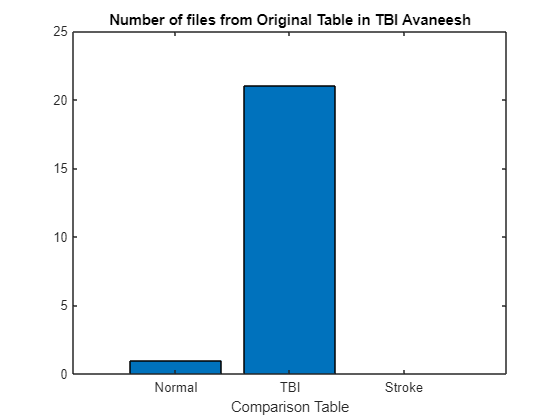

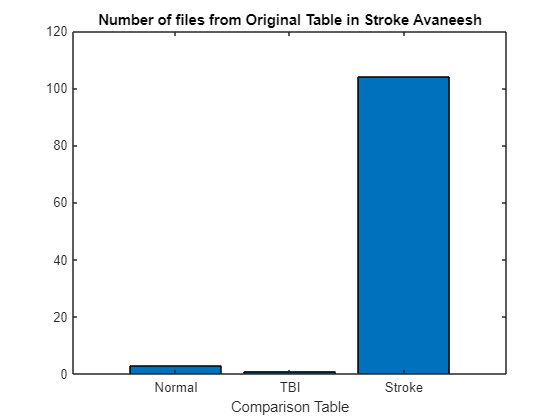

filesO = Compare(Avaneesh,Original,"Normal","TBI","Stroke");

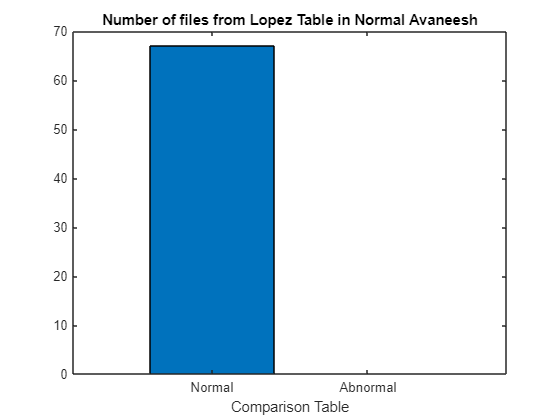

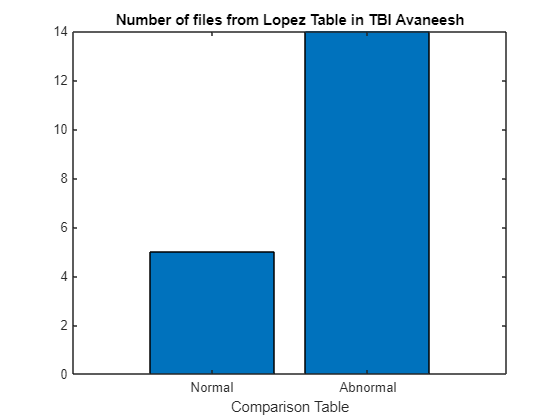

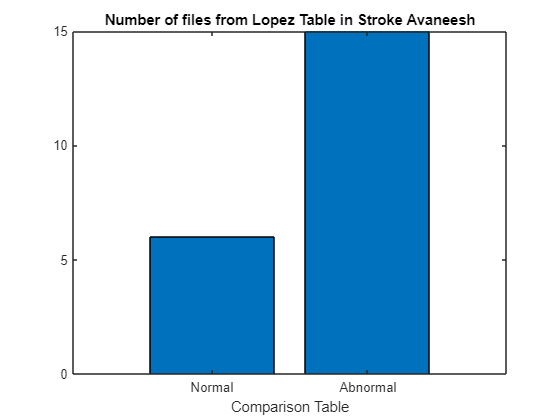

files1 = Compare(Avaneesh,Lopez,"Normal","Abnormal");

- Remove Original TBI from normal

- Remove abnormal from normal and normal from TBI/Stroke.

- Add remaning Lopez Healthy? No

- Other way? Yep

- Do a subject match. Mixed Cohort - > Unknown. Cohort + unknown -> cohort? after BERT

- Word Clouds

- BERT

### Original Data Comparison

Check out Original TBI classified as normal.

Data = Avaneesh;
[inT,inA] = Index(Data,Original);
disp(Data.A.("Full Note")(inA(logical(filesO{1}(:,2)))));

    "CLINICAL HISTORY: This is a 44-year-old male who fell from a ladder with loss of consciousness and concussion for four to five days. No history of seizures.↵MEDICATIONS: None.↵INTRODUCTION: Digital video EEG is performed in the lab using standard 10-20 system of electrode placement with one channel of EKG. Hyperventilation and photic stimulation were performed.  This is an awake and drowsy record.↵DESCRIPTION OF THE RECORD: In wakefulness, the background EEG is well organized with a rich, 11.5 Hz, 30 to 60 uV posterior dominant rhythm and a generous amount of low voltage, frontocentral beta activity.  Drowsiness is characterized by attenuation of the alpha rhythm with a more diffuse distribution of the beta activity.  Photic stimulation elicits bilateral driving with a photoelectric response.  Hyperventilation elicits an increase in amplitude and a small degree of background slowing.↵HR:  56 - 80 BPM.↵IMPRESSION: Normal EEG in wakefulness and brief drowsiness.↵CLINICAL CORRELATION

Convert these two to TBI

Data.A.Category(inA(logical(filesO{1}(:,2)))) = "TBI";

Check out Original normal classified as TBI.

disp(Data.A.("Full Note")(inA(logical(filesO{2}(:,1)))));

CLINICAL HISTORY: This is a 17-year-old male with a skull defect with a gun shot wound to the head, right ear pain, and headaches.
MEDICATIONS: Dilantin, others.
INTRODUCTION: Digital video EEG is performed at the bedside using standard 10-20 system of electrode placement with one channel of EKG. This is primarily an asleep record.
DESCRIPTION OF THE RECORD: Drowsiness is characterized by slow rolling eye movements with rhythmic background theta.  Vertex waves, K complexes, and spindles are identified in stage II sleep.  On one occasion, there are POSTS identified, which are higher amplitude on the right in comparison to the left.  Brief arousal of the patient produces an alerting with an increase in beta, but wakefulness is not sustained.
HR:  60 to 116 BPM.
IMPRESSION: EEG within normal limits in sleep.
CLINICAL CORRELATION: The higher amplitude POSTS on the right compared to the left may be related to the patient’s previous craniotomy and are of unclear clinical significance.  If th

Data.A.Category(inA(logical(filesO{2}(:,1)))) = "TBI";

Check out Original normal classified as Stroke.

disp(Data.A.("Full Note")(inA(logical(filesO{3}(:,1)))));

    "CLINICAL HISTORY: This is a 56-year-old male with congestive heart failure, CVA, and pacemaker.↵MEDICATIONS: Digoxin, _______check tech sheet___, aspirin, Vasotec.↵INTRODUCTION: Digital video EEG is performed at the bedside using standard 10-20 system of electrode placement with one channel of EKG. Photic stimulation and hyperventilation were not performed. This is mainly an asleep record.↵DESCRIPTION OF THE RECORD: A posterior dominant rhythm of 8.5 Hz is identified.  In stage I sleep, POSTS and beta activity are seen, as well as EKG artifact.  During the majority of the study, the patient is persistently sleepy and there is only a limited period of wakefulness.↵HR:  72 BPM, irregular.↵IMPRESSION: Normal EEG within limited wakefulness.↵CLINICAL CORRELATION: This patient was excessively sleepy, possibly due to sleep deficit or secondary to medication.↵↵↵↵↵"
    "CLINICAL HISTORY: This is a 37-year-old woman with headache versus TIA versus stroke, right-sided weakness, and history 

These look like Stroke.

Check out Original TBI classified as Stroke.

disp(Data.A.("Full Note")(inA(logical(filesO{3}(:,2)))));

CLINICAL HISTORY:  53 year old left handed male with prior EEGs, presents with status in the past and hypoxic injury as well as history of CVA, hep C, cirrhosis, and TBI who now is having myoclonic jerks.

MEDICATIONS:  Keppra, Ceftriaxone, Vancomycin, Zosyn, Heparin

REASON FOR STUDY:  Rule out seizures; patient having myoclonic jerks.

INTRODUCTION:  Digital video EEG was performed in lab using the standard 10-20 electrode placement system with additional anterior temporal and single-lead EKG electrodes.  The patient was unresponsive during the EEG.  No activating procedures were performed.

TECHNICAL DIFFICULTIES:   None

DESCRIPTION OF THE RECORD:  The record opens to a diffusely slow background with a frequency of 2 to 4 Hz and an amplitude of 20 to 30 microvolts.  There is no normal posterior dominant rhythm or frontocentral beta.  There appears to be no clear reactivity.  During the recorded video, there appears to be some sudden jerks with the typical appearance of myoclonus; h

Stroke and TBI - > Unknown

Data.A.Category(inA(logical(filesO{3}(:,2)))) = "Unknown";

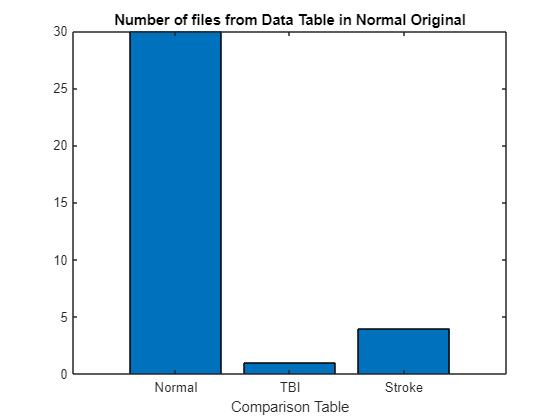

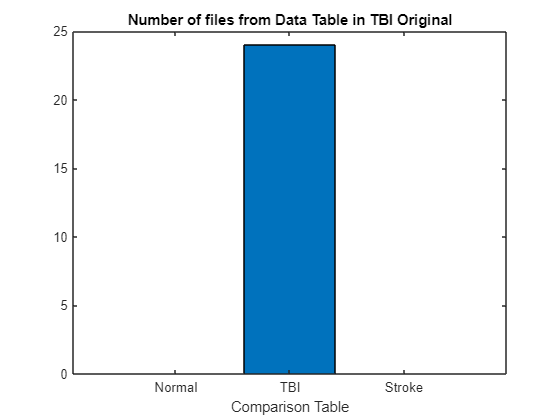

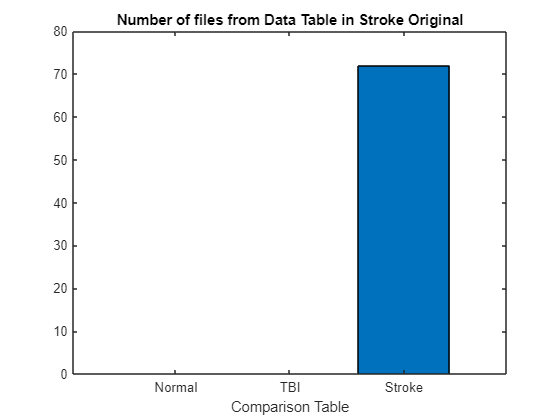

filesOr = Compare1(Data,Original,"Normal","TBI","Stroke");

Check out TBI in Normal Original.

disp(Data.A.("Full Note")(logical(filesOr{1}(:,2))));

CLINICAL HISTORY: This is a 17-year-old male with a skull defect with a gun shot wound to the head, right ear pain, and headaches.
MEDICATIONS: Dilantin, others.
INTRODUCTION: Digital video EEG is performed at the bedside using standard 10-20 system of electrode placement with one channel of EKG. This is primarily an asleep record.
DESCRIPTION OF THE RECORD: Drowsiness is characterized by slow rolling eye movements with rhythmic background theta.  Vertex waves, K complexes, and spindles are identified in stage II sleep.  On one occasion, there are POSTS identified, which are higher amplitude on the right in comparison to the left.  Brief arousal of the patient produces an alerting with an increase in beta, but wakefulness is not sustained.
HR:  60 to 116 BPM.
IMPRESSION: EEG within normal limits in sleep.
CLINICAL CORRELATION: The higher amplitude POSTS on the right compared to the left may be related to the patient’s previous craniotomy and are of unclear clinical significance.  If th

These are fine.

Check out Stroke in Normal Original.

disp(Data.A.("Full Note")(logical(filesOr{1}(:,3))));

    "CLINICAL HISTORY: This is a 56-year-old male with congestive heart failure, CVA, and pacemaker.↵MEDICATIONS: Digoxin, _______check tech sheet___, aspirin, Vasotec.↵INTRODUCTION: Digital video EEG is performed at the bedside using standard 10-20 system of electrode placement with one channel of EKG. Photic stimulation and hyperventilation were not performed. This is mainly an asleep record.↵DESCRIPTION OF THE RECORD: A posterior dominant rhythm of 8.5 Hz is identified.  In stage I sleep, POSTS and beta activity are seen, as well as EKG artifact.  During the majority of the study, the patient is persistently sleepy and there is only a limited period of wakefulness.↵HR:  72 BPM, irregular.↵IMPRESSION: Normal EEG within limited wakefulness.↵CLINICAL CORRELATION: This patient was excessively sleepy, possibly due to sleep deficit or secondary to medication.↵↵↵↵↵"
    "CLINICAL HISTORY: This is a 37-year-old woman with headache versus TIA versus stroke, right-sided weakness, and history 

These are fine.

Check out Normal in TBI Original.

disp(Data.A.("Full Note")(logical(filesOr{2}(:,1))));
%Data.A.Category(logical(filesOr{2}(:,1))) = categorical(["TBI";"TBI"]);

Check out Stroke in TBI Original.

disp(Data.A.("Full Note")(logical(filesOr{2}(:,3))));
%Data.A.Category(logical(filesOr{2}(:,3))) = "Unknown";

### Lopez Data Comparison

Check out Lopez Normal classified as TBI.

[inT,inA] = Index(Data,Lopez);
disp(Data.A.("Full Note")(inA(logical(files1{2}(:,1)))));

    "↵CLINICAL HISTORY: →80 year old woman with recent trauma status post fall due to unsteady gait. Had episode of eye twitching and myoclonic jerking of the arms and episodically of the legs. Indications to rule out seizure activity. Past medical history of A. fib, TIA, pacemaker.↵↵MEDICATIONS:  Cymbalta, Percocet,  ASA,Cymbalta, Clonazepam, Vicodin, Lovenox, Lotensin, Norvasc, Loratadine↵↵INTRODUCTION:  Digital video EEG was performed in lab using standard 10-20 system of electrode placement with 1 channel  of EKG. Photic simulation was performed.↵↵DESCRIPTION OF THE RECORD: This is a well-organized symmetric EEG. There is alpha of 8-9 Hz throughout the record. The amplitude is mildly high for patient's age but this is nonspecific. There is some muscle artifact due to shaking episodes, however there are no EEG correlates to the shaking activity. Photic stimulation does not activate the record.↵↵HR: →72 bpm and  regular.↵↵↵IMPRESSION:  Normal EEG.↵↵CLINICAL CORRELATION:   There is no

Data.A.Category(inA(logical(files1{2}(:,1)))) = categorical(["Unknown";"TBI";"TBI";"Unknown";"Unknown"]) ;

Check out Lopez Normal classified as Stroke.

disp(Data.A.("Full Note")(inA(logical(files1{3}(:,1)))));

    "CLINICAL HISTORY:  78 year old right handed female who has a history of strokes in↵2007 with subsequent seizures. She was complaining of lightheadedness. She denied any further seizure activity since 2007.↵↵MEDICATIONS:  Citalopram, Enalapril, Atenolol, Lovastatin, Aggrenox, Roxicet, hydrochlorothiazide, Glipizide, Oxycodone↵↵INTRODUCTION: Digital video EEG was performed in lab using standard 10-20 system of electrode placement with 1 channel of EKG. Hyperventilation and photic simulation are performed.↵↵DESCRIPTION OF  THE RECORD:  In wakefulness, the background EEG is low voltage, but there is 9.5 hertz symmetric reactive alpha rhythm. Features of drowsiness include an increase in beta. Rare, isolated right or left temporal theta/delta is noted in drowsiness.  Photic stimulation elicits bilateral driving.↵↵HR:→66 bpm↵↵↵IMPRESSION: EEG within normal limits in wakefulness and drowsiness.↵↵↵CLINICAL CORRELATION:   No epileptiform features were noted. A normal EEG does not exclude a

Data.A.Category(inA(logical(files1{3}(:,1)))) = categorical(["Unknown";"Stroke";"Unknown";"Unknown";"Unknown";"Unknown"]) ;

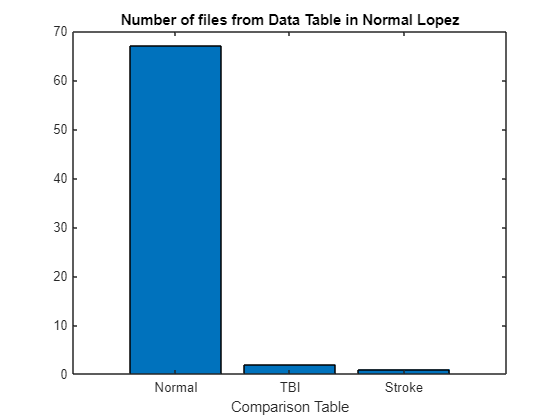

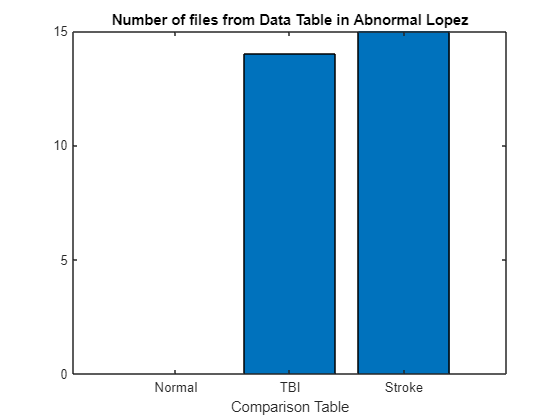

files1r = Compare1(Data,Lopez,"Normal","Abnormal");

Check out TBI in Normal Lopez.

disp(Data.A.("Full Note")(logical(files1r{1}(:,2))));

    "CLINICAL HISTORY:  51 year old right handed woman with syncope and headaches, past history of closed head injury in June 2011.↵MEDICATIONS:  HCTZ, Lymphedema, Aspirin, Omeprazole.↵INTRODUCTION:  Digital video EEG is performed in lab using standard 10-20 system of electrode placement with 1 channel EKG.  Hyperventilation and photic stimulation were performed.↵DESCRIPTION OF THE RECORD:  In wakefulness, there is a 9 Hz symmetric reactive alpha rhythm with a small amount of low voltage, frontal central beta.  Central mu activity is noted, but testing is not performed to confirm this. Hyperventilation produces an increase in amplitude of the background and a small amount of slowing. Features of drowsiness include slow rolling eye movements, attenuation of the alpha, and POSTS.↵Photic stimulation elicits vigorous bilateral driving.↵HR:    72 bpm↵IMPRESSION:  Normal EEG.↵CLINICAL CORRELATION:  No focal nor epileptiform features were observed.  Normal EEG does not exclude a diagnosis of 

Data.A.Category(logical(files1r{1}(:,2))) = categorical(["TBI";"TBI"]);

Check out Stroke in Normal Lopez.

disp(Data.A.("Full Note")(logical(files1r{1}(:,3))));

CLINICAL HISTORY: 62 year old woman with a stroke and intermittent episodes of left facial spasms and twitching. Past history of atherosclerosis.
MEDICATIONS: Aricept, Plavix, Metoprolol, Pravachol
INTRODUCTION: Digital video EEG was performed in lab using standard 10-20 system of electrode placement with 1 channel of EKG. This is an awake and drowsy record with photic stimulation.
DESCRIPTION OF THE RECORD: In wakefulness, there is a 10.5 Hz posterior dominant rhythm of 30 mcv with a generous amount of tow voltage, frontocentral beta activity. Frequent eye blink artifact is observed. Photic stimulation elicits bilateral driving.
HR: 90 bpm

IMPRESSION: EEG within normal limits.
CLINICAL CORRELATION: No significant focal features nor epileptiform features are observed. There is a single burst of slowing in the transition to drowsiness which is considered a normal finding in an adult of this age. Additional EEG recording capturing one of her spells may be of use, given the frequency of 

Data.A.Category(logical(files1r{1}(:,3))) = categorical(["Stroke"]);

## Remove subjects with multiple classes

in = unique(Data.A.Subject,'rows','stable');
for i = 1: length(in)
    in2 = Data.A.Category(Data.A.Subject == in(i));
    h = histcounts(in2);
    if logical(h(2:end)>1)
        Data.A.Category(Data.A.Subject == in(i)) = "Unknown";
    end
end

## New Database

NumSubjects(Avaneesh);

Number of Total subjects: 3938
Number of Normal subjects: 1054
Number of TBI subjects: 326
Number of Stroke subjects: 488


NumSubjects(Data);

Number of Total subjects: 3938
Number of Normal subjects: 1051
Number of TBI subjects: 328
Number of Stroke subjects: 487


## Word Clouds

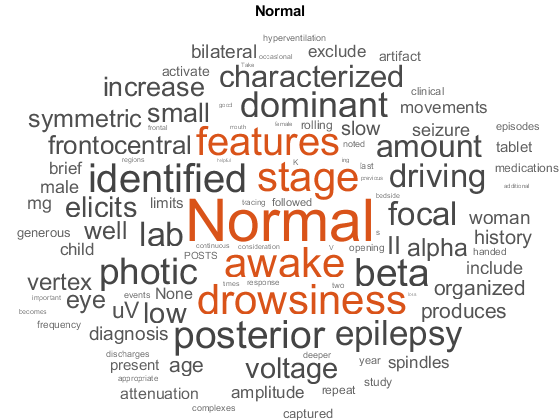

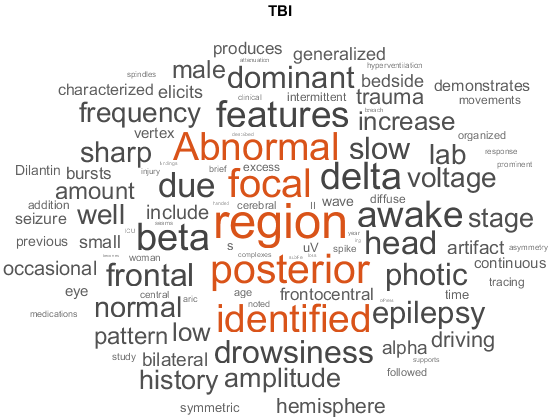

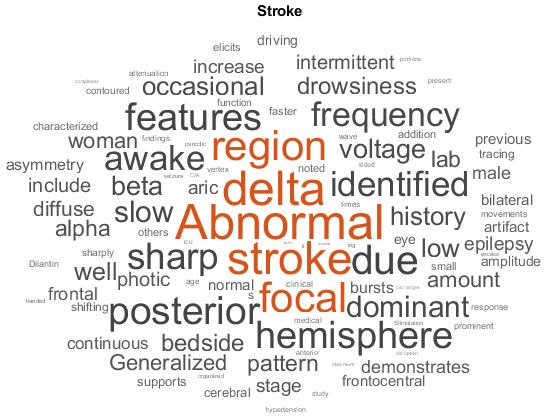

PlotWordClouds(Data,36);

## BERT

path = pwd;
bertfol = 'C:\Users\nonun\Documents\GitHub\transformer-models';
cd(bertfol)
mdl = bert

mdl = struct with fields:
     Tokenizer: [1×1 bert.tokenizer.BERTTokenizer]
    Parameters: [1×1 struct]


View the BERT model tokenizer. The tokenizer encodes text as sequences of integers and holds the details of padding, start, separator and mask tokens.

tokenizer = mdl.Tokenizer

tokenizer =   BERTTokenizer with properties:

      PaddingToken: "[PAD]"
        StartToken: "[CLS]"
    SeparatorToken: "[SEP]"
         MaskToken: "[MASK]"
     FullTokenizer: [1×1 bert.tokenizer.internal.FullTokenizer]
       PaddingCode: 1
     SeparatorCode: 103
         StartCode: 102
          MaskCode: 104


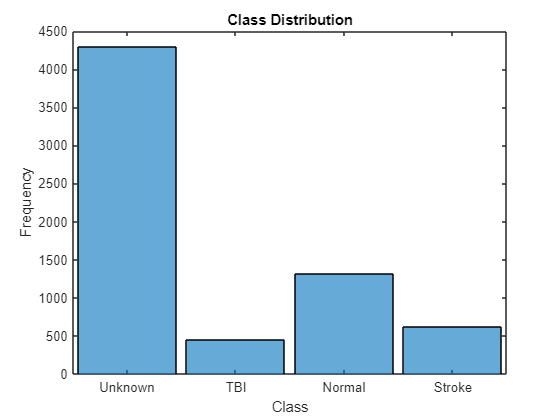

figure
histogram(Data.A.Category);
xlabel("Class")
ylabel("Frequency")
title("Class Distribution")

Encode the text data using the BERT model tokenizer using the `encode` function and add the tokens to the training data table.

data = Data.A;
data.Tokens = encode(tokenizer, data.("Full Note"));

classes = categories(data.Category);
numClasses = numel(classes)

numClasses = 4

Balance large unknown group

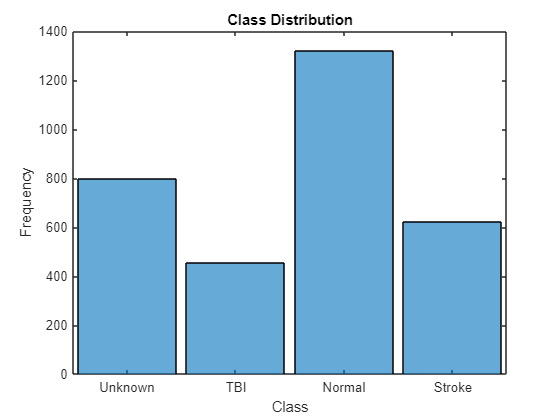

cd(path);
smallergroup = ceil(sum(data.Category~="Unknown")/(numClasses-1)); %make average size
in = data.Category== "Unknown";
in = find(in);
in = in(randperm(length(in)));
in = in(1:smallergroup);
data = [data(in,:);data(data.Category~="Unknown",:)];
figure
histogram(data.Category);
xlabel("Class")
ylabel("Frequency")
title("Class Distribution")

The next step is to partition it into sets for training and validation. Partition the data into a training partition and a held-out partition for validation and testing. Specify the holdout percentage to be 20%.

cvp = cvpartition(data.Category,"Holdout",0.2);
dataTrain = data(training(cvp),:);
dataValidation = data(test(cvp),:);

View the number of training and validation observations.

numObservationsTrain = size(dataTrain,1)

numObservationsTrain = 2556

numObservationsValidation = size(dataValidation,1)

numObservationsValidation = 639

Extract the text data, labels, and encoded BERT tokens from the partitioned tables.

textDataTrain = dataTrain.("Full Note");
textDataValidation = dataValidation.("Full Note");

TTrain = dataTrain.Category;
TValidation = dataValidation.Category;

tokensTrain = dataTrain.Tokens;
tokensValidation = dataValidation.Tokens;


To check that you have imported the data correctly, visualize the training text data using a word cloud.

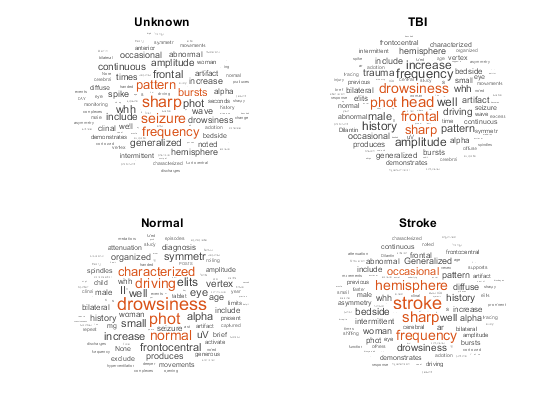

c = categories(data.Category);
pat = regexpPattern('[A-Z\s]*[A-Z]+:');
x = data.("Full Note");
x = erase(x,pat); % Remove capital headings
wc = wordCloudCounts(x);
wc = wc{1:50,1};
x = erase(x,wc);
x = erase(x,"ic");
x = replace(x,regexpPattern('\s[a-z][\s\*\)\.\,]')," ");
x = replace(x,"  "," ");
wc = wordCloudCounts(x);
figure
for i = 1: 4
    nexttile();
    in = data.Category == c(i);
    y = x(in);
    wordcloud(y)
    title(c(i))
end

View the BERT token codes of the first few training documents.

tokensTrain{1:5}

ans =          102        6613        2382        1025        2024        2004        1038        2049        1012        3205        1012        2215        2932        2008        5306        2572        3527        4296        2180        2631        2000        1997        2228        1013        2382        1998       12668        2616        1999        9707       22085        1013       20993        1025        7280       28776       21203        1013        4956        1025        3618        2679       25213        2291        2004        2865        2000        1997       13641        2479


ans =          102        6613        2382        1025        2024        2004        1038        4294        1012        2096        1012        2215        3288        2008        1038        3161        1998        3672        3779       18480        3402       21891        7394        1011       11722        4184        8762        1011        1999        5902       13994       10700        3854        1013       20993        1025        8841       20111        2954        1013        4956        1025        3618        2679       25213        2291        2004        2865        2000        1997


ans =          102        6613        2382        1025        2024        2004        1038        6164        1012        2096        1012        2215        2932        2008       28390        1040        1999        5730       16342        2000        5178        3571        1013       20993        1025       22823       20739        1011        2013       11445        2079        1011       22954        5303       23236        3171        1013        4956        1025        3618        2679       25213        2291        2004        2865        2013        1997       19476        2000        1997


ans =          102        6613        2382        1025        4230        2096        2215        2451        2008        1038        2382        1998        1038        2188       15851        6081       12799       29481        2864        3571        2696       24502       18492        2000        2269        1011        2008       25751        2000        1997        2628        1022        2707        2650        2005        2384        3240       25403        1013       20993        1025       17711        9398        2528        1011        4488        7104        2079        1013        3115


ans =          102        6613        2382        1025        2024        2004        1038        6164        1012        2096        1012        2215        2451        2008        2020        2020       11237        7275        2214       12529        2005        2093        2005        1038        6394        8572        1999        4583       11751        1011       20993        1025        4014        4144        2279        1011       29455        4631        2379        1011        2328        8068        2596        1011        1999        2117        2501        1013        4956        1025


### Prepare Data for Training

Convert the documents to feature vectors using the BERT model as a feature extractor.

% To extract the features of the training data by iterating over
% mini-batches, create a |minibatchqueue| object.

% Mini-batch queues require a single datastore that outputs both the
% predictors and responses. Create array datastores containing the training
% BERT tokens and labels and combine them using the |combine| function.
dsXTrain = arrayDatastore(tokensTrain,"OutputType","same");
dsTTrain = arrayDatastore(TTrain);
cdsTrain = combine(dsXTrain,dsTTrain);

% Create a combined datastore for the validation data using the same steps.
dsXValidation = arrayDatastore(tokensValidation,"OutputType","same");
dsTValidation = arrayDatastore(TValidation);
cdsValidation = combine(dsXValidation,dsTValidation);

Create a mini-batch queue for the training data. Specify a mini-batch size of 32 and preprocess the mini-batches using the `preprocessPredictors` function, listed at the end of the example.

miniBatchSize = 32;
paddingValue = mdl.Tokenizer.PaddingCode;
maxSequenceLength = mdl.Parameters.Hyperparameters.NumContext;

mbqTrain = minibatchqueue(cdsTrain,1,...
    "MiniBatchSize",miniBatchSize, ...
    "MiniBatchFcn",@(X) preprocessPredictors(X,paddingValue,maxSequenceLength));

Create a mini-batch queue for the validation data using the same steps.

mbqValidation = minibatchqueue(cdsValidation,1,...
    "MiniBatchSize",miniBatchSize, ...
    "MiniBatchFcn",@(X) preprocessPredictors(X,paddingValue,maxSequenceLength));

To speed up feature extraction. Convert the BERT model weights to gpuArray if a GPU is available.

if canUseGPU
    mdl.Parameters.Weights = dlupdate(@gpuArray,mdl.Parameters.Weights);
end

Convert the training sequences of BERT model tokens to a `N`-by-|embeddingDimension| array of feature vectors, where `N` is the number of training observations and `embeddingDimension` is the dimension of the BERT embedding.

cd(bertfol)
featuresTrain = [];
reset(mbqTrain);
while hasdata(mbqTrain)
    X = next(mbqTrain);
    features = bertEmbed(X,mdl.Parameters);
    featuresTrain = [featuresTrain gather(extractdata(features))];
end

Transpose the training data to have size `N`-by-|embeddingDimension|.

featuresTrain = featuresTrain.';

Convert the validation data to feature vectors using the same steps.

featuresValidation = [];

reset(mbqValidation);
while hasdata(mbqValidation)
    X = next(mbqValidation);
    features = bertEmbed(X,mdl.Parameters);
    featuresValidation = cat(2,featuresValidation,gather(extractdata(features)));
end
featuresValidation = featuresValidation.';
cd(path);

### Define Deep Learning Network

Define a deep learning network that classifies the feature vectors.

numFeatures = mdl.Parameters.Hyperparameters.HiddenSize;
layers = [
    featureInputLayer(numFeatures)
    dropoutLayer(.05)
    %fullyConnectedLayer(100)
    reluLayer()         
    dropoutLayer(.2)
    fullyConnectedLayer(4)
    softmaxLayer
    classificationLayer];

### Specify Training Options

Specify the training options using the `trainingOptions` function. * Train with a mini-batch size of 64. * Shuffle the data every epoch. * Validate the network using the validation data. * Display the training progress in a plot and suppress the verbose output.

opts = trainingOptions('adam',...
    "MiniBatchSize",64,...
    "ValidationData",{featuresValidation,dataValidation.Category},...
    "Shuffle","every-epoch", ...
    "Plots","training-progress","MaxEpochs",400, "InitialLearnRate",.01,"LearnRateSchedule","piecewise","LearnRateDropPeriod",100,...
    "Verbose",0);

classificationSVM = fitcecoc(...
    featuresTrain, ...
    dataTrain.Category);
kfoldmodel = crossval(classificationSVM, 'KFold', 5);
predLabels = kfoldPredict(kfoldmodel);
loss = kfoldLoss(kfoldmodel)*100;
fprintf('Loss is %2.2f percent\n',loss);

Loss is 34.94 percent


accuracy = 100-loss;
fprintf('Accuracy is %2.2f percent\n',accuracy);

Accuracy is 65.06 percent


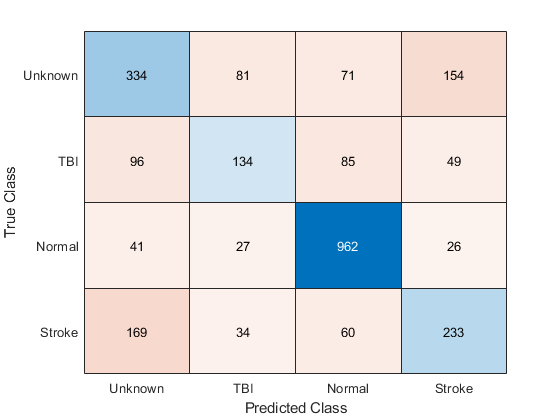

figure;
confmatCV = confusionchart(dataTrain.Category,predLabels);

### Train Network

Train the network using the `trainNetwork` function.

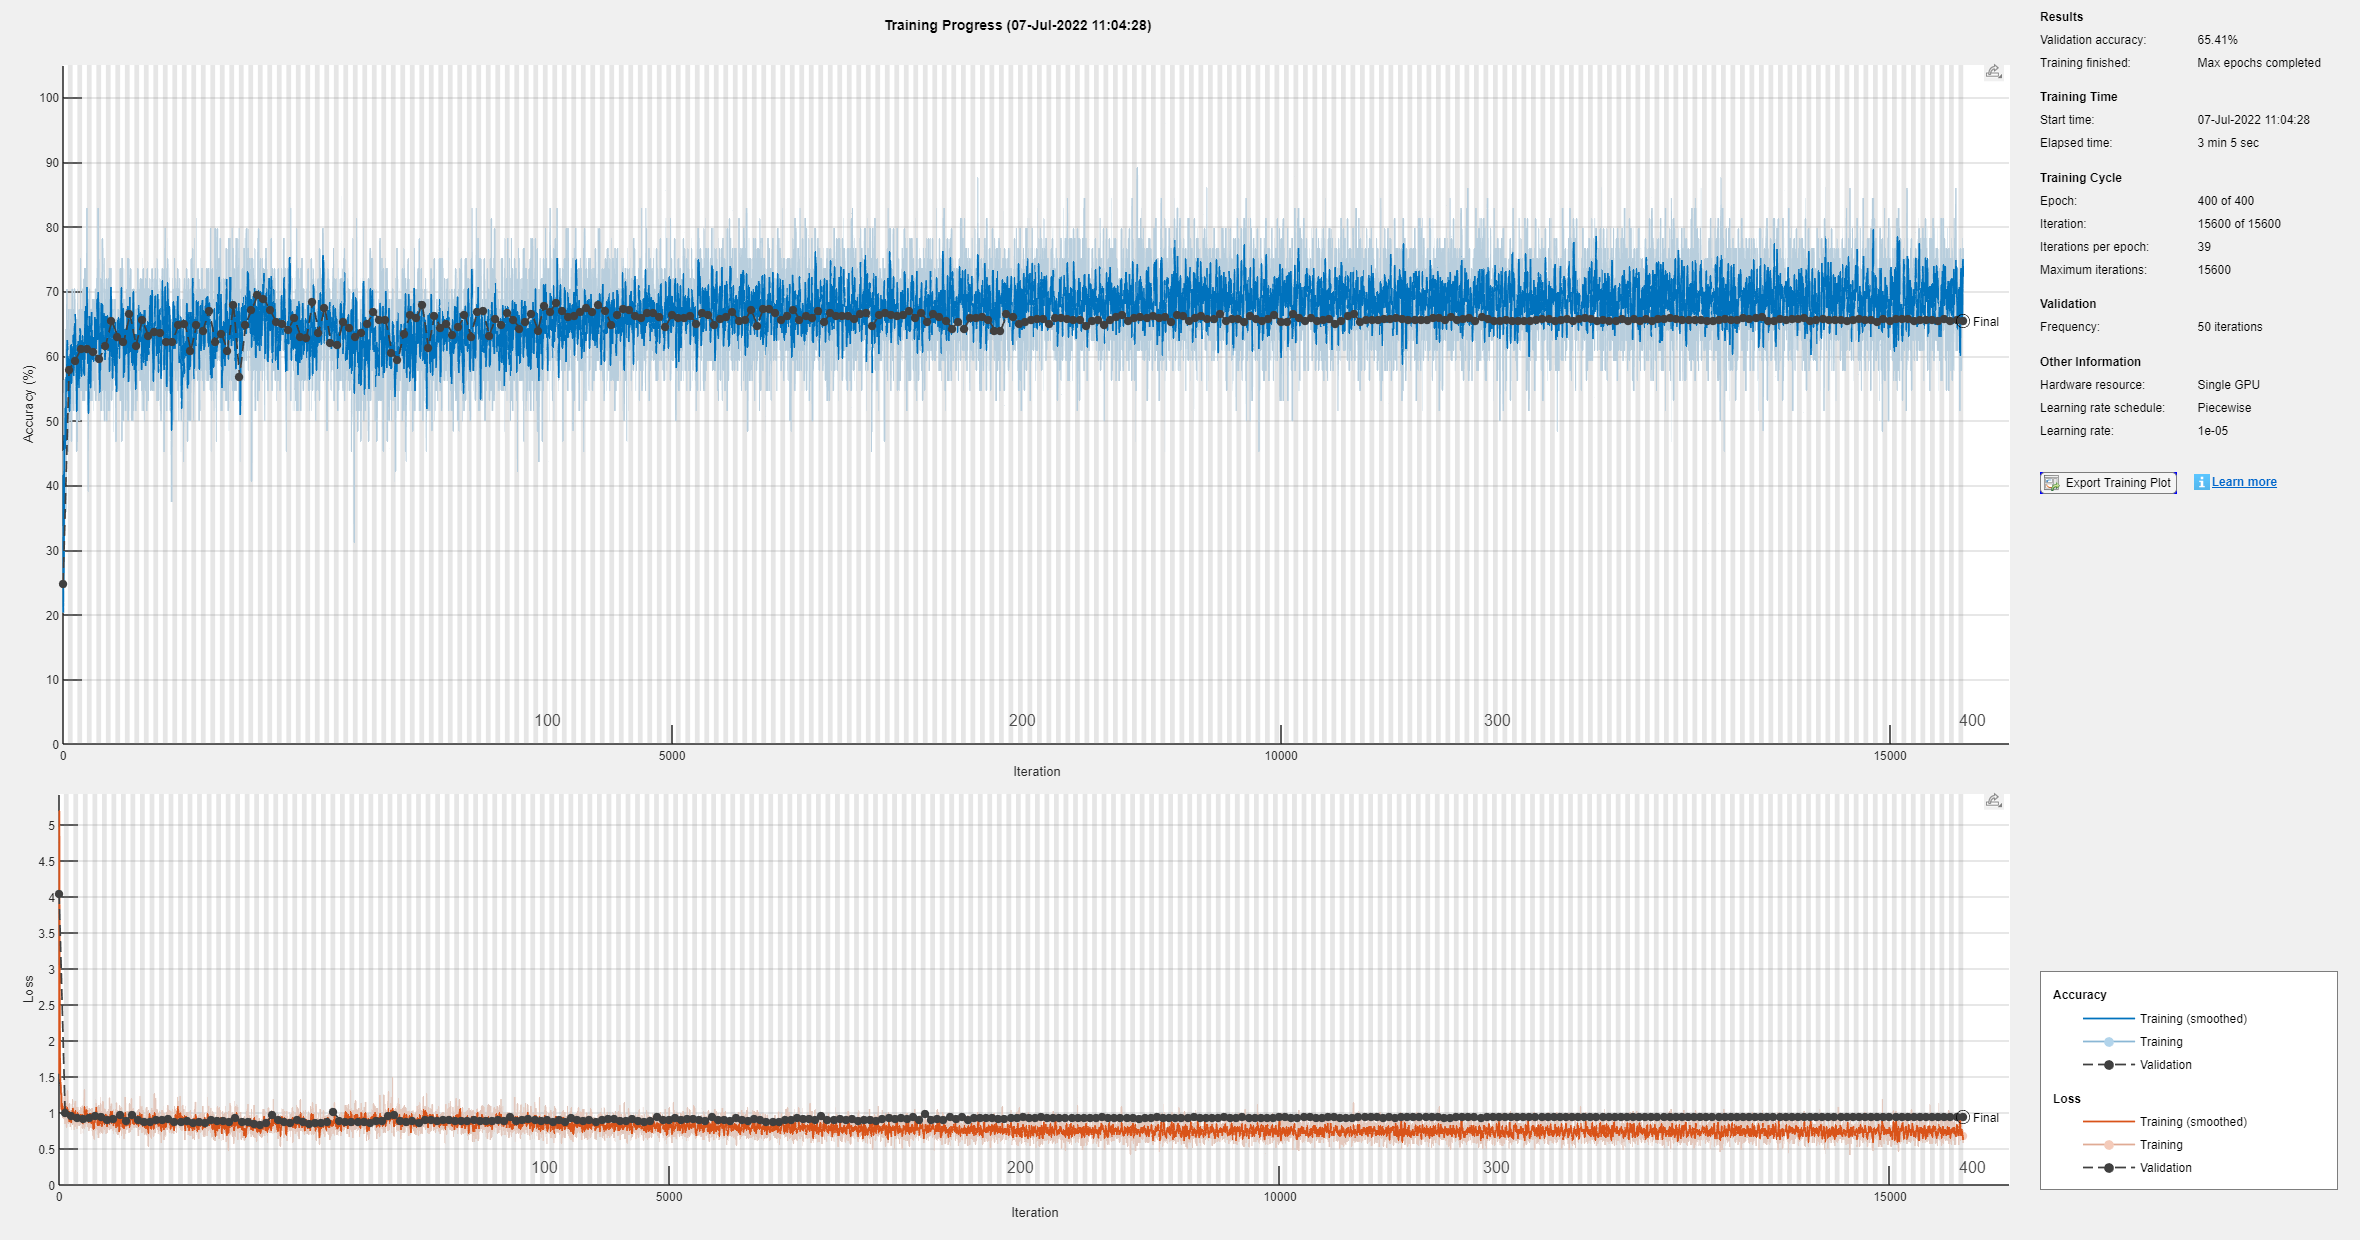

%net = trainNetwork(featuresTrain,dataTrain.Category,layers,opts);
load("Pretextnet.mat")

### Test Network

Make predictions using the validation data and display the results in a confusion matrix.

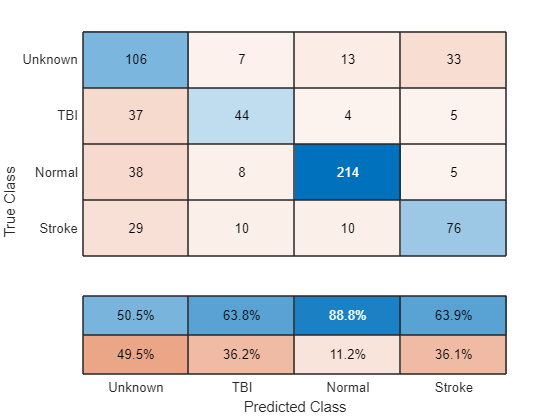

[YPredValidation,score] = classify(net,featuresValidation);
figure
cm = confusionchart(TValidation,YPredValidation);
cm.ColumnSummary = 'column-normalized';

Calculate the validation accuracy.

accuracy = mean(dataValidation.Category == YPredValidation)

accuracy = 0.6886

Calculate calidation accuracy 

precision = (sum(diag(cm.NormalizedValues))-cm.NormalizedValues(1,1))/sum(cm.NormalizedValues(:,2:end),'all')

precision = 0.7786

meanprecision = sum(([0, ones(1,4-1)] .* diag(cm.NormalizedValues)')./[1 sum(cm.NormalizedValues(:,2:end))])/(4 - 1)

meanprecision = 0.7214

### Using confident answers

Taking only confident answers (example: score >.7) or unknown

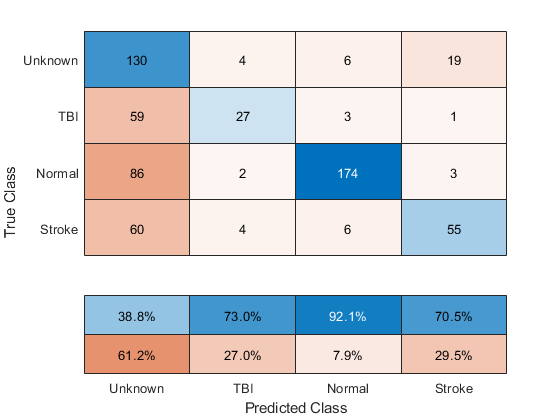

V = table(YPredValidation,score(:,1),score(:,2),score(:,3),score(:,4),'VariableNames',{'Prediction',classes{1},classes{2},classes{3},classes{4}});
V = [dataValidation(:,4) V];
[p, pm] = precisionChart(.9,score,classes,V);

disp("Precision is " + p)

Precision is 0.84211


disp("Mean precision is " + pm)

Mean precision is 0.78516


#### What is the relation of the confidence to precision and correctly labled predictions?

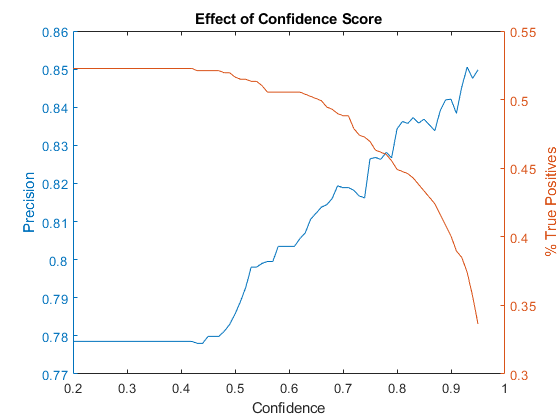

p = [];
r = [];
k = 1;
ran = .2:.01:.95;
for i = ran
    confidx = i;
    V = table(YPredValidation,score(:,1),score(:,2),score(:,3),score(:,4),'VariableNames',{'Prediction',classes{1},classes{2},classes{3},classes{4}});
    V = [dataValidation(:,4) V];
    [max_score, pred_in] = max(score,[],2);
    in = max_score > confidx;
    pred_in(~in) = find(string(classes) == "Unknown");
    V.Confident = categorical(string(classes(pred_in)));
    figure
    cm = confusionmat(V.Category,V.Confident);
    p(k) = (sum(diag(cm))-cm(1,1))/sum(cm(:,2:end),'all');
    r(k) = (sum(diag(cm))-cm(1,1))/sum(cm,'all');
    k = k+1;
end
figure;
yyaxis left
plot(ran,p)
ylabel("Precision")
hold on
yyaxis right
plot(ran,r)
xlabel("Confidence")
ylabel("% True Positives")
title("Effect of Confidence Score")

With a large enough database we can value higher precsion over loss of datapoints.

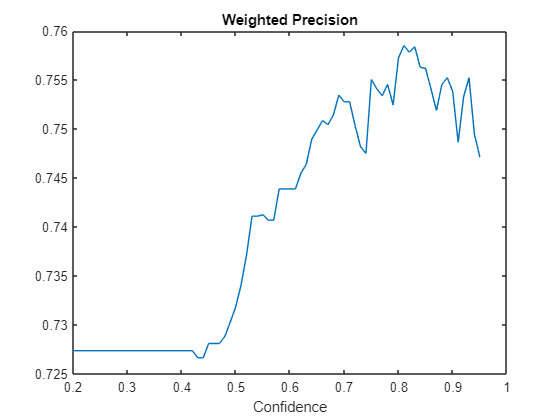

w = 4; % weighted term
x = (w*p + r)/(w+1);
figure
plot(ran, x)
xlabel("Confidence")
title("Weighted Precision")

maxPrescison = ran(x == max(x));
disp("Use a confidence score of " + maxPrescison + " to maximize the weighted precision score")

Use a confidence score of 0.81 to maximize the weighted precision score


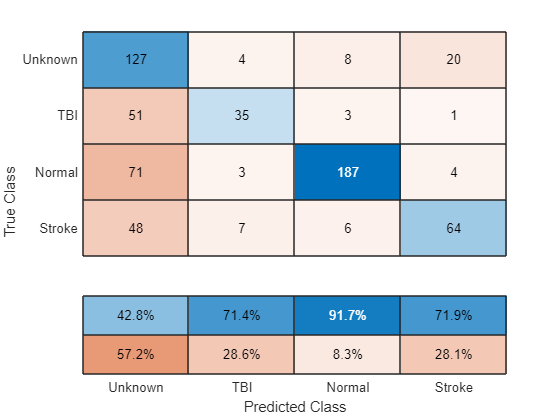

[p, pm] = precisionChart(ran(x == max(x)),score,classes,V);

disp("Precision is " + p)

Precision is 0.83626


### Predict New Data

Find Data in AllFiles and remove it. Then predict NewFiles category and put back together.

ind = [];
for i = 1:height(Data.A)
    ind = [ind; find(and(AllFiles.A.Subject==Data.A.Subject(i), AllFiles.A.Session==Data.A.Session(i)))];
end
newin = zeros(1,height(AllFiles.A));
newin(ind) = 1;
newin = logical(newin);

newtext = string(AllFiles.A.("Full Note")(~newin));

Tokenize the text data using the same steps as the training documents.

cd(bertfol)
tokensNew = encode(tokenizer,newtext);

Create minibatch

dsXNew = arrayDatastore(tokensNew,"OutputType","same");

mbqNew = minibatchqueue(dsXNew,1,...
    "MiniBatchSize",miniBatchSize, ...
    "MiniBatchFcn",@(X) preprocessPredictors(X,paddingValue,maxSequenceLength));

Make new predictions

pred = [];
score = [];
reset(mbqNew);
while hasdata(mbqNew)
    X = next(mbqNew);
    y = bertEmbed(X,mdl.Parameters)';
    y = gather(extractdata(y));
    [a,b] = classify(net,y);
    pred = [pred; a];
    score = [score; max(b,[],2)];
end
cd(path)

Add confident predictions

pin = score > maxPrescison;
disp("Number of Normal files predicted: " + sum(pred(pin)=="Normal"));

Number of Normal files predicted: 2907


disp("Number of TBI files predicted: " + sum(pred(pin)=="TBI"));

Number of TBI files predicted: 1166


disp("Number of Stroke files predicted: " + sum(pred(pin)=="Stroke"));

Number of Stroke files predicted: 2571


T = AllFiles.A;
in = find(~newin);
T.Score(in) = score;
T.Category(in(pin)) = pred(pin);
T.Category(ind) = Data.A.Category;
T.Score(ind) = 1;
T.Category = categorical(T.Category);

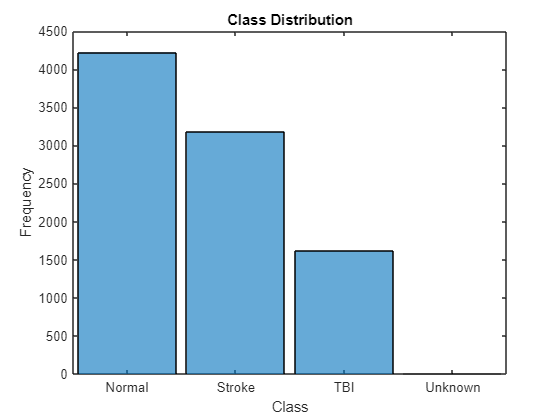

figure
histogram(T.Category(T.Category~="Unknown"));
xlabel("Class")
ylabel("Frequency")
title("Class Distribution")

disp("TBI records:" + sum(T.Category=="TBI"))

TBI records:1614


disp("STR records:" + sum(T.Category=="Stroke"))

STR records:3185


disp("HEA records:" + sum(T.Category=="Normal"))

HEA records:4223


## Final Curation

### Remove subjects with multiple classes

in = unique(T.Subject,'rows','stable');
for i = 1: length(in)
    in2 = T.Category(T.Subject == in(i));
    h = histcounts(in2);
    if logical(h(2:end)>1)
        T.Category(T.Subject == in(i)) = "Unknown";
    end
end

### Check for seizure and epilepsy

Seizure Check 1

%Checks for obvious seizures
sin2 = contains(T.("Full Note"),"with " + optionalPattern("recurrent ") + "seizure","IgnoreCase",true);
cin = T.Category ~= "Unknown";
in = sin2 & cin;
S = T(in,:);
disp("Check table S with " + height(S) + " entries")

Check table S with 368 entries


Update

S.Category(:) = "Unknown";
T(in,:) = S;

Seizure Check 2

%Checks for seizure but excludes "seizure free" records
sin = contains(T.("Full Note"),"seizure","IgnoreCase",true);
sinf1 = contains(T.("Full Note"),"seizure-free","IgnoreCase",true);
sinf2 = contains(T.("Full Note"),"seizure free","IgnoreCase",true);
sinf3 = contains(T.("Full Note"),"no seizure","IgnoreCase",true);
sinf4 = contains(T.("Full Note"),"If seizures are an important consideration","IgnoreCase",true);
sinf = sinf1 | sinf2 | sinf3 | sinf4;
cin = T.Category ~= "Unknown";

Check table S with 3049 entries


in = sin & cin & ~sinf;
S = T(in,:);
disp("Check table S with " + height(S) + " entries")

Update

S.Category(:) = "Unknown";
T(in,:) = S;

in = and(contains(T.("Full Note"),"Evaluate for seizure","IgnoreCase",true), contains(T.("Full Note"),"brain injury","IgnoreCase",true));
S = T(in,:);
disp("Check table S with " + height(S) + " entries")

Check table S with 1 entries


Manual Update

T(in,:) = S;

in = or(contains(T.("Full Note"),"Evaluate for seizure versus stroke","IgnoreCase",true),contains(T.("Full Note"),"Evaluate for stroke versus seizure","IgnoreCase",true));
S = T(in,:);
disp("Check table S with " + height(S) + " entries")

Check table S with 7 entries


Manual Update

T(in,:) = S;

### Age

in = and(T.Age>=18,T.Age<=65);
T = T(in,:);

### Alzheimer/Dementia Keywords

in = and(or(contains(T.("Full Note"),"Alzheim","IgnoreCase",true),contains(T.("Full Note"),"dement","IgnoreCase",true)),T.Category~="Unknown");
S = T(in,:);
subs = unique(S.Subject);
sin = ismember(T.Subject,subs);
T.Category(sin) = "Unknown";

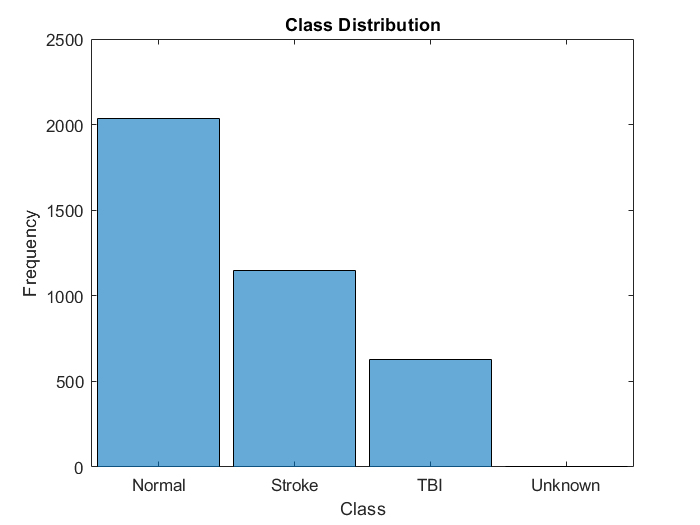

PredictedFiles = CohortFiles(T);
figure
histogram(T.Category(T.Category~="Unknown"));
xlabel("Class")
ylabel("Frequency")
title("Class Distribution")

disp("TBI records:" + sum(T.Category=="TBI"))

TBI records:629


disp("STR records:" + sum(T.Category=="Stroke"))

STR records:1146


disp("HEA records:" + sum(T.Category=="Normal"))

HEA records:2033


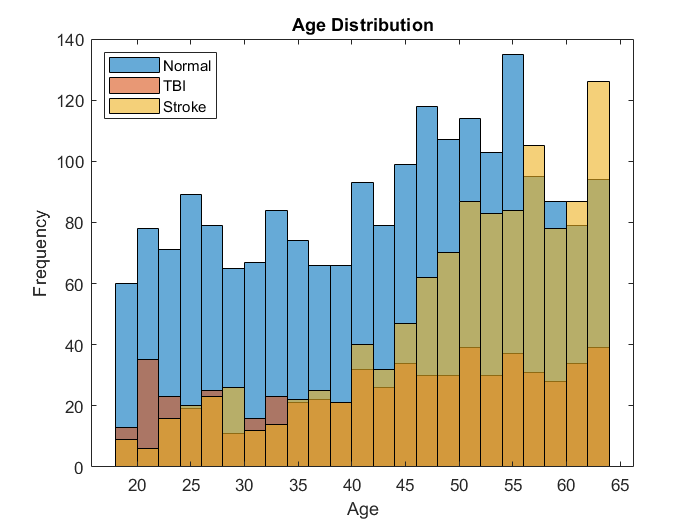

figure;
histogram(T.Age(T.Category=="Normal"),18:2:65);
hold on
histogram(T.Age(T.Category=="TBI"),18:2:65);
histogram(T.Age(T.Category=="Stroke"),18:2:65);
xlabel Age
ylabel Frequency
title("Age Distribution")
legend(["Normal","TBI","Stroke"],'Location',"northwest");

### Final World Clouds

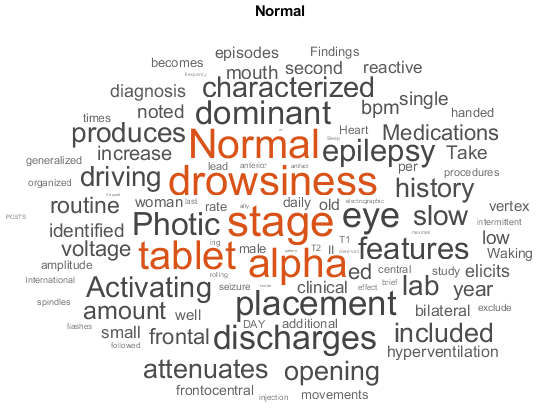

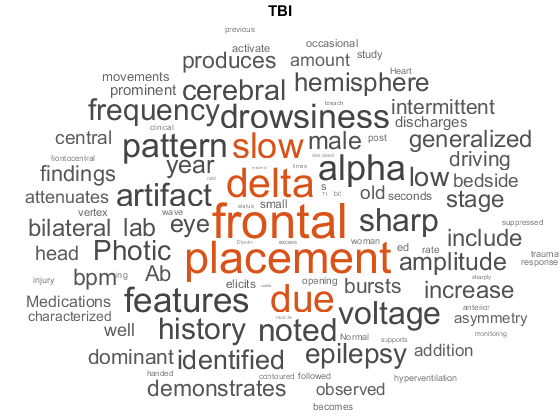

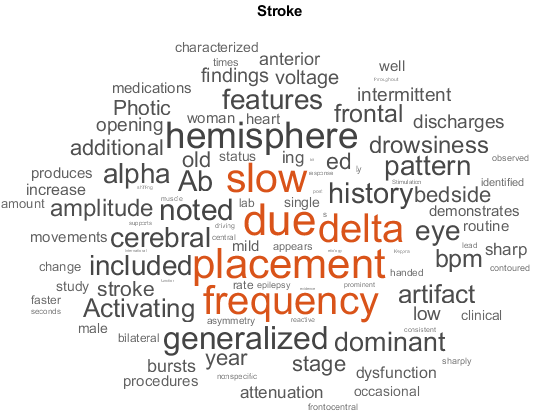

PlotWordClouds(PredictedFiles);

Save T

save("PredictionDatabase.mat",'T','net','PredictedFiles')

## Supporting Functions

function T = GetLopezData(file)
filename = "";
categ = "";
k = 1;
fol1 = ["eval", "train"];
fol2 = ["abnormal","normal"];
for f = fol1
    for f2 = fol2
        path = fullfile(file,f,f2,"01_tcp_ar");
        d = dir(path);
        for i = 3:length(d)
            d1 = dir(fullfile(d(i).folder,d(i).name));
            for j1 = 3:length(d1)
                d2 = dir(fullfile(d1(j1).folder,d1(j1).name));
                for j2 = 3:length(d2)
                    d3 = dir(fullfile(d2(j2).folder,d2(j2).name,"*.txt"));
                    filename(k) = d3.name;
                    if f2=="abnormal"
                        categ(k) = "Abnormal";
                    else
                        categ(k) = "Normal";
                    end
                    k = k+1;
                end
            end
        end
    end
end
T = table(filename',categorical(categ'),'VariableNames',["Filename","Category"]);
sub=[];
ses=[];
for i = height(T):-1:1
    s = split(T.Filename(i),"_");
    sub(i) = str2double(s(1));
    s = split(s(2),".");
    s = split(s(1),"s");
    ses(i) = str2double(s(2));
end
T.Subject = sub';
T.Session = ses';
save("LopezData.mat","T");
end
function X = preprocessPredictors(X,paddingValue,maxSeqLen)

X = truncateSequences(X,maxSeqLen);
X = padsequences(X,2,"PaddingValue",paddingValue);

end

### BERT Embedding Function

The `bertEmbed` function maps input data to embedding vectors and optionally applies dropout using the "DropoutProbability" name-value pair.

function Y = bertEmbed(X,parameters,args)

arguments
    X
    parameters
    args.DropoutProbability = 0
end

dropoutProbabilitiy = args.DropoutProbability;

Y = bert.model(X,parameters, ...
    "DropoutProb",dropoutProbabilitiy, ...
    "AttentionDropoutProb",dropoutProbabilitiy);

% To return single feature vectors, return the first element.
Y = Y(:,1,:);
Y = squeeze(Y);

end

### Confusion Chart Function

function [p,pm] = precisionChart(confidx,score,classes,V)
numClasses = length(classes);
[max_score, pred_in] = max(score,[],2);
in = max_score > confidx;
pred_in(~in) = find(string(classes) == "Unknown");
V.Confident = categorical(string(classes(pred_in)));
figure
cm = confusionchart(V.Category,V.Confident);
cm.ColumnSummary = 'column-normalized';
p = (sum(diag(cm.NormalizedValues))-cm.NormalizedValues(1,1))/sum(cm.NormalizedValues(:,2:end),'all');
pm = sum(([0, ones(1,numClasses-1)] .* diag(cm.NormalizedValues)')./[1 sum(cm.NormalizedValues(:,2:end))])/(numClasses - 1);
end